# Anti transformada de Laplace

clear all;
clc;
close all;

## Referência

https://lpsa.swarthmore.edu/LaplaceXform/InvLaplace/InvLaplaceXformPFE.html

## Exemplo 01


$$G(s) = \frac{s+1}{s(s+2)}$$


N = [1 1];
D = [1 2 0];
G1 = tf(N,D);

[r,p,k] = residue(N,D)

r =     0.5000
    0.5000


p =     -2
     0



k =

     []



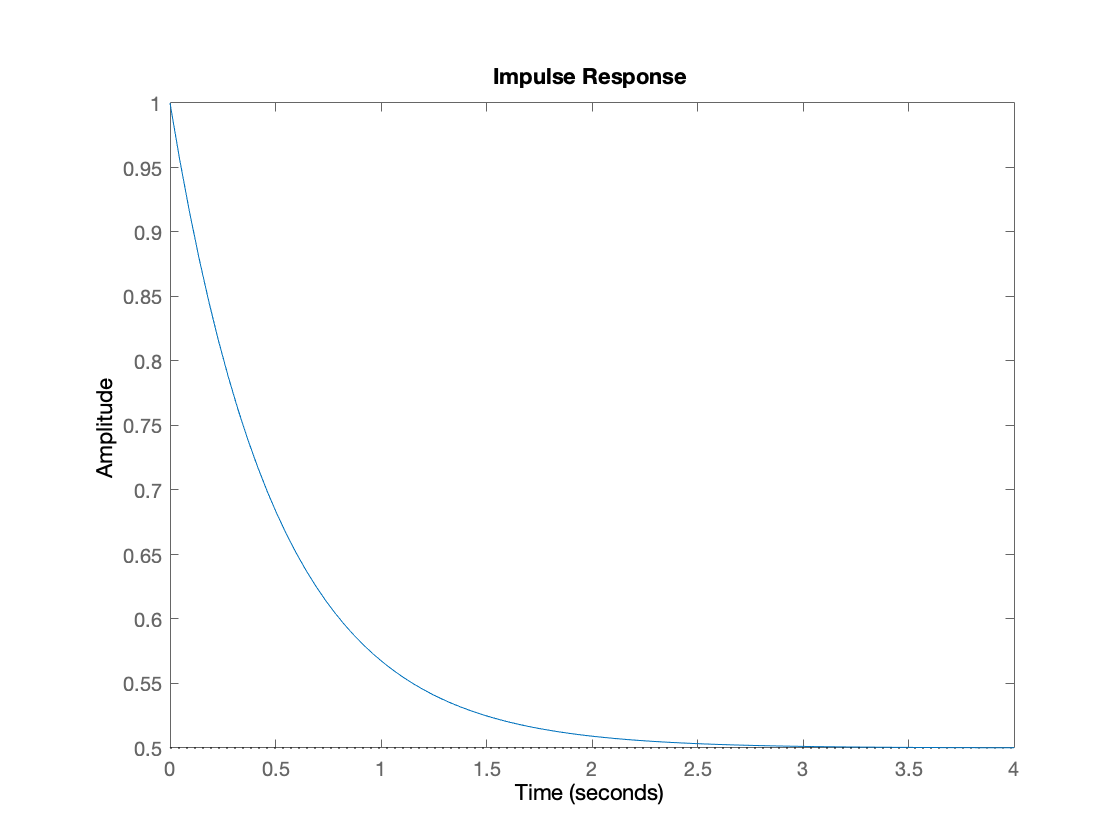


impulse(G1)

## Resíduos


$$G(s) = \frac{r(1)}{s-p(1)} +  \frac{r(2)}{s-p(2)}$$


## Exemplo 02


$$G(s) = \frac{s^2+1}{s^2(s+2)}$$


N =  [1 0 1];
D =  [1 2 0 0];
G2 = tf(N,D);

[r,p,k] = residue(N,D)

r =     1.2500
   -0.2500
    0.5000


p =     -2
     0
     0



k =

     []



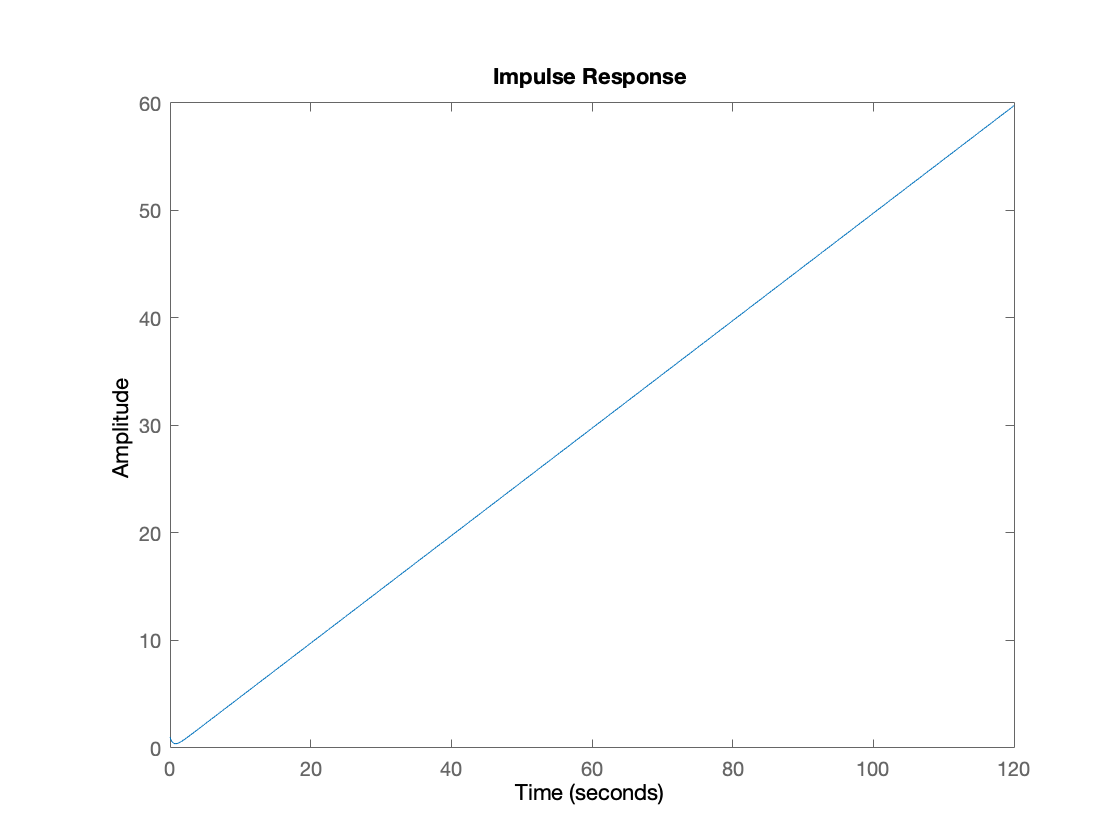


impulse(G2)

## Analisando cada termo

G21 = r(1)*tf(1,[1 2])

G21 =
 
  1.25
  -----
  s + 2
 
Continuous-time transfer function.



G22 = r(2)*tf(1,[1 0])

G22 =
 
  -0.25
  -----
    s
 
Continuous-time transfer function.



G23 = r(3)*tf(1,[1 0 0])

G23 =
 
  0.5
  ---
  s^2
 
Continuous-time transfer function.



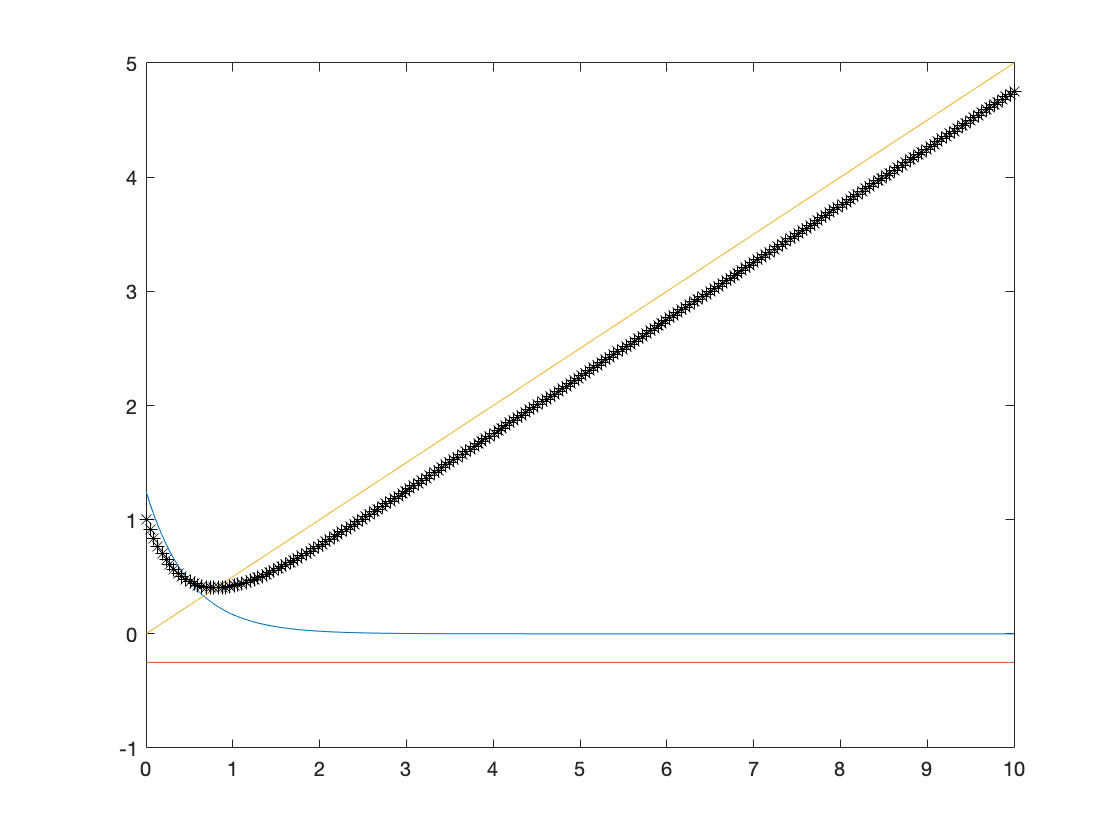


close all;

[Y21,T21] = impulse(G21,10);
[Y22,T22] = impulse(G22,10);
[Y23,T23] = impulse(G23,10);
[Y,T] = impulse(G2,10);

plot(T21,Y21,T22,Y22,T23,Y23,T,Y,'k*')

## Exemplo 03


$$G(s) = \frac{s+3}{(s+5)(s^2+4s+5)}$$


N =  [1 3];
D =  conv([1 5],[1 4 5]);
G3 = tf(N,D)

G3 =
 
           s + 3
  -----------------------
  s^3 + 9 s^2 + 25 s + 25
 
Continuous-time transfer function.




[r,p,k] = residue(N,D)

r =   -0.2000 + 0.0000i
   0.1000 - 0.2000i
   0.1000 + 0.2000i


p =   -5.0000 + 0.0000i
  -2.0000 + 1.0000i
  -2.0000 - 1.0000i



k =

     []



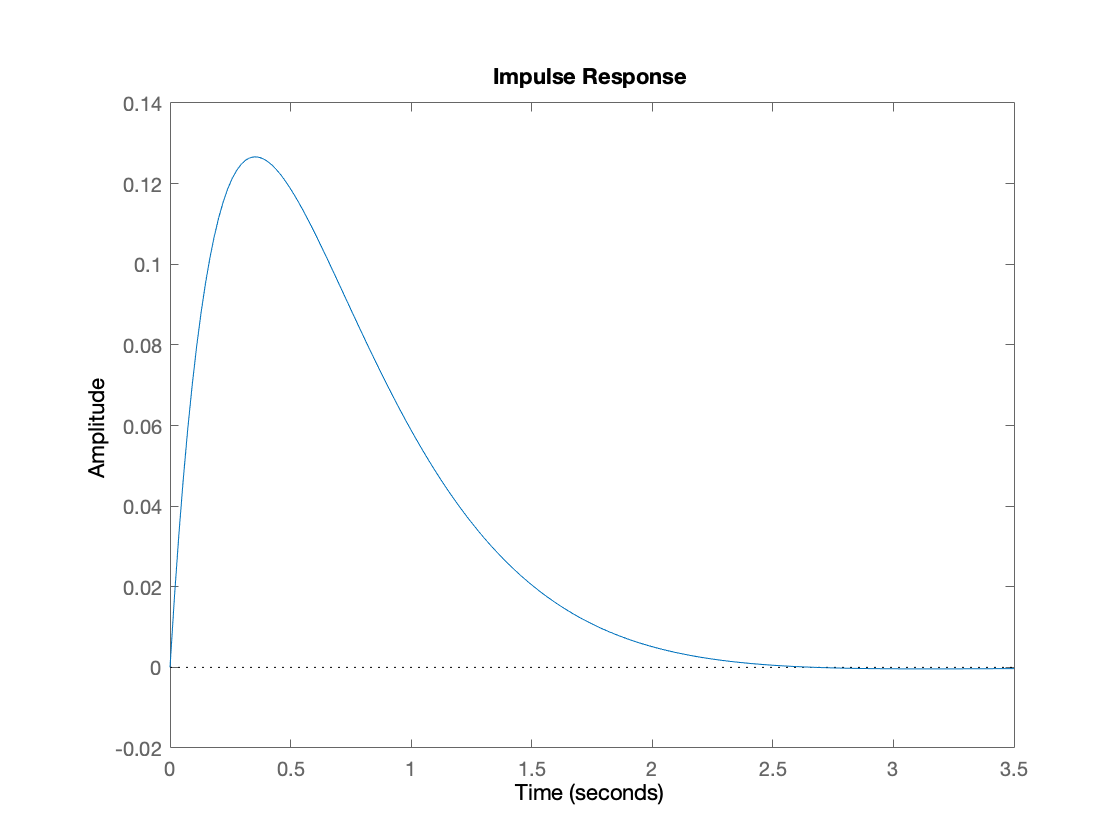


impulse(G3)

## Exemplo 04


$$G(s) = \frac{5s^2+8s-5}{s^2(s^2+2s+5)}$$


## Exemplo 05


$$G(s) = \frac{3s^2+2s+3}{s^2+3s+2}$$
